clc; clearvars; close all;

## Filter data based on Pandora Location and day of week

% Select which Pandora sites to include in processing
CCNY =          true; % City College
NYBG =          false; % New York Botanical Gardens
QueensCollege = false; % Queens College
Beltsville =    false; % Beltsville
Eessex =        false; % Essex
Greenbelt2 =    false; % Greenbelt2
Greenbelt32 =   false; % Greenbelt32
DC =            false; % Washington DC
NewBrunswick =  false; % New Brunswick
NewHaven =      false; % New Haven
Cornwall =      false; % Cornwall

% Select if weekdays, weekends, or both should be used
weekdays = "all";

% Select whether to include only high NO2, low NO2, or all (as measured by Pandora)
high_no2 = "all";
no2_cutoff = 200;

save_figs = true;
fig_dim = [0 0 1000 1000];
% fig_folder = 'C:/NERTO_drive/figures_ams';
fig_folder = 'C:\Users\Thomas\OneDrive\Desktop';

site_flags = [CCNY NYBG QueensCollege Beltsville Eessex Greenbelt2 Greenbelt32 DC NewBrunswick NewHaven Cornwall];
sites = ["ccny" "nybg" "queens" "beltsville" "essex" "greenbelt2" "greenbelt32" "DC" "new_brunswick" "new_haven" "cornwall"];
sites_in_use = sites(site_flags);

tempo_table = table;
tropomi_table = table;
pandora_table = table;
merged_table = table;
for i = 1:length(sites_in_use)
    current_site = sites_in_use(i);

    % Load Tempo data
    tempo_file = dir(['.\validation\time_series_data\tempo_',char(current_site),'.mat']);
    tempo = load(fullfile(tempo_file.folder,tempo_file.name));
    temp_tempo = tempo.data_table;
    temp_tempo.site = repmat(current_site, [size(temp_tempo,1),1]);
    
    % Load Tropomi data
    tropomi_file = dir(['.\validation\time_series_data\tropomi_',char(current_site),'.mat']);
    tropomi = load(fullfile(tropomi_file.folder,tropomi_file.name));
    temp_tropomi = tropomi.data_table;
    temp_tropomi.site = repmat(current_site, [size(temp_tropomi,1),1]);

    % Load Pandora Data
    pandora_file = dir(['.\validation\time_series_data\',char(current_site),'_pandora_data.mat']);
    pandora = load(fullfile(pandora_file.folder,pandora_file.name));
    temp_pandora = pandora.pandora_data;
    temp_pandora.site = repmat(current_site, [size(temp_pandora,1),1]);

    % Load Merged Data
    merged_file = dir(['.\validation\time_series_data\merged_',char(current_site),'.mat']);
    merged = load(fullfile(merged_file.folder,merged_file.name));
    temp_merged = merged.data_table;
    temp_merged.site = repmat(current_site, [size(temp_merged,1),1]);

    tempo_table = [tempo_table; rmmissing(temp_tempo)];
    tropomi_table = [tropomi_table; rmmissing(temp_tropomi)];
    pandora_table = [pandora_table; rmmissing(temp_pandora)];
    merged_table = [merged_table; rmmissing(temp_merged)];
end

clear temp_tempo temp_tropomi temp_pandora temp_merged

% Load CCNY Ground Monitor Data
ccny_ground_no2 = load("./validation/time_series_data/ground_monitor.mat");
ccny_ground_no2 = table2timetable(ccny_ground_no2.ccny_ground_no2);
ccny_ground_no2.Date_Time_UTC_.TimeZone = 'UTC';
ccny_ground_no2.Date_Time_Local_.TimeZone = 'local';
ccny_ground_no2(ccny_ground_no2.NO2Conc<0,:) = [];

## Filter based on data quality

need to do a loop that filters the data based on difference criteria and calculates the statistics for that scenario

all data, weekdays, weekends, high no2, low no2 measured by pandora

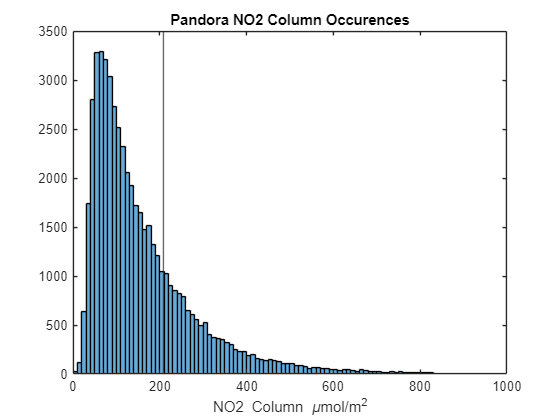

% TEMPO high quality filter
tempo_cld_frac_threshold = 0.15;
tempo_rowfilter = rowfilter(["vertical_column_troposphere","main_data_quality_flag", "solar_zenith_angle", "viewing_zenith_angle", "eff_cloud_fraction", "site", "time"]);
tempo_filter = tempo_rowfilter.vertical_column_troposphere>=0 & (tempo_rowfilter.main_data_quality_flag==0 | tempo_rowfilter.main_data_quality_flag==1) & tempo_rowfilter.solar_zenith_angle<70 & tempo_rowfilter.viewing_zenith_angle<70 & tempo_rowfilter.eff_cloud_fraction<tempo_cld_frac_threshold;

% TROPOMI high quality filter
tropomi_qa_threshold = 0.75;
tropomi_rowfilter = rowfilter(["qa_value","nitrogendioxide_tropospheric_column", "site", "time"]);
tropomi_filter = tropomi_rowfilter.qa_value>=tropomi_qa_threshold & tropomi_rowfilter.nitrogendioxide_tropospheric_column>=0;

% Pandora high quality filter
pandora_quality = "medium";
pandora_rowfilter = rowfilter(["qa", "NO2", "site", "Date"]);

% Merged high quality filter
merged_rowfilter = rowfilter(["vertical_column_troposphere", "site", "time"]);
merged_filter = merged_rowfilter.vertical_column_troposphere>=0;

if pandora_quality == "high"
    pandora_filter = pandora_rowfilter.NO2>=0 & (pandora_rowfilter.qa == 0 | pandora_rowfilter.qa == 10);
elseif pandora_quality == "medium"
    pandora_filter = pandora_rowfilter.NO2>=0 & (pandora_rowfilter.qa == 0 | pandora_rowfilter.qa == 1 | pandora_rowfilter.qa == 10 | pandora_rowfilter.qa == 11);
end

% Apply filters to tables
tempo_filtered = tempo_table(tempo_filter,:);
tropomi_filtered = tropomi_table(tropomi_filter,:);
pandora_filtered = pandora_table(pandora_filter,:);
merged_filtered = merged_table(merged_filter,:);

% convert tables to timetables
tempo_filtered = tempo_table2timetable(tempo_filtered);
tropomi_filtered = tropomi_table2timetable(tropomi_filtered);
pandora_filtered = table2timetable(pandora_filtered);
merged_filtered = merged_table2timetable(merged_filtered);

% Change units in tempo tables
tempo_filtered.vertical_column_troposphere = tempo_filtered.vertical_column_troposphere ./ conversion_factor('trop-tempo') .*10^6;
tempo_filtered.vertical_column_troposphere_uncertainty = tempo_filtered.vertical_column_troposphere_uncertainty ./ conversion_factor('trop-tempo') .* 10^6;

tropomi_filtered.nitrogendioxide_tropospheric_column = tropomi_filtered.nitrogendioxide_tropospheric_column .*10^6;
tropomi_filtered.nitrogendioxide_tropospheric_column_precision = tropomi_filtered.nitrogendioxide_tropospheric_column_precision .* 10^6;

pandora_filtered.NO2 = pandora_filtered.NO2 .*10^6;

merged_filtered.vertical_column_troposphere = merged_filtered.vertical_column_troposphere .*10^6;
merged_filtered.vertical_column_troposphere_uncertainty = merged_filtered.vertical_column_troposphere_uncertainty .* 10^6;

figure;
histogram(pandora_filtered.NO2)
xlim([0 1000])
xlabel('NO2 Column \mumol/m^2')
title('Pandora NO2 Column Occurences')
xline(prctile(pandora_filtered.NO2,75))

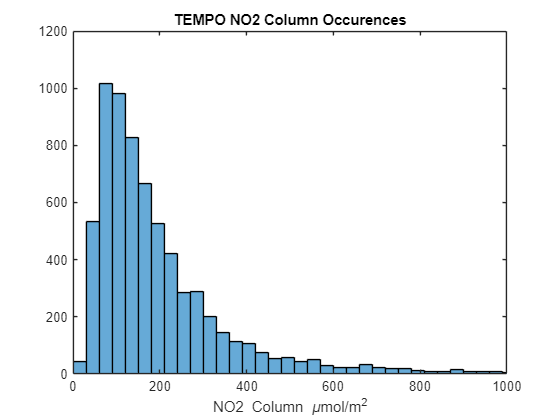


figure;
histogram(tempo_filtered.vertical_column_troposphere)
xlim([0 1000])
xlabel('NO2 Column \mumol/m^2')
title('TEMPO NO2 Column Occurences')

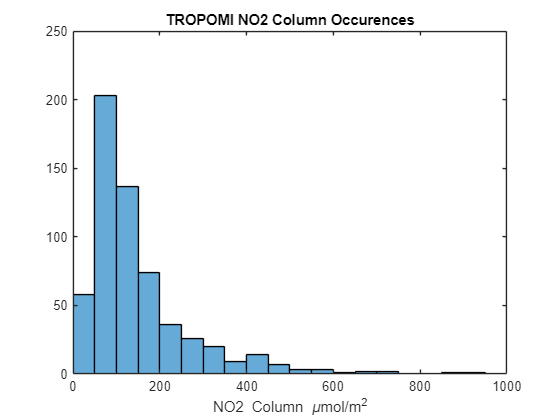


figure;
histogram(tropomi_filtered.nitrogendioxide_tropospheric_column)
xlim([0 1000])
xlabel('NO2 Column \mumol/m^2')
title('TROPOMI NO2 Column Occurences')

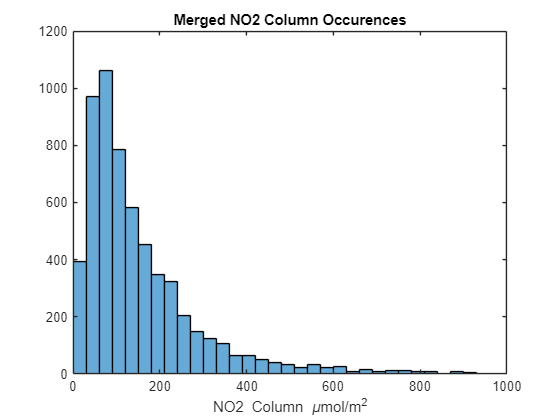


figure;
histogram(merged_filtered.vertical_column_troposphere)
xlim([0 1000])
xlabel('NO2 Column \mumol/m^2')
title('Merged NO2 Column Occurences')

## Apply Scenario Filters

% Filter all data by day of the week
if weekdays == "weekdays"
    tempo_filtered = tempo_filtered(~isweekend(tempo_filtered.time),:);
    tropomi_filtered = tropomi_filtered(~isweekend(tropomi_filtered.time),:);
    pandora_filtered = pandora_filtered(~isweekend(pandora_filtered.Date),:);
    merged_filtered = merged_filtered(~isweekend(merged_filtered.time),:);
elseif weekdays == "weekends"
    tempo_filtered = tempo_filtered(isweekend(tempo_filtered.time),:);
    tropomi_filtered = tropomi_filtered(isweekend(tropomi_filtered.time),:);
    pandora_filtered = pandora_filtered(isweekend(pandora_filtered.Date),:);
    merged_filtered = merged_filtered(isweekend(merged_filtered.time),:);
elseif weekdays == "all"
    % do nothing
end

% Filter Pandora data by NO2 amount
if high_no2 == "high"
    pandora_filtered = pandora_filtered(pandora_filtered.NO2 >= no2_cutoff,:);
elseif high_no2 == "low"
    pandora_filtered = pandora_filtered(pandora_filtered.NO2 < no2_cutoff,:);
elseif high_no2 == "all"
    % do nothing
end

## Plot data over time

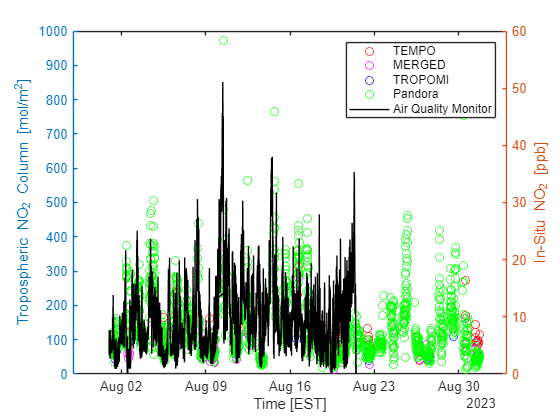

% change this binning
site_to_plot = sites_in_use(1);
binning =      "none";
start_day = datetime("2023-08-01", "InputFormat", "uuuu-MM-dd"); start_hour =0;
end_day =   datetime("2023-08-31", "InputFormat", "uuuu-MM-dd"); end_hour =0;

tz = 'America/New_York';
start_day.TimeZone = tz;
end_day.TimeZone = tz;

plot_period = timerange(start_day, end_day);

tempo_plot_filter = tempo_rowfilter.site == site_to_plot & tempo_rowfilter.time>=start_day & tempo_rowfilter.time<end_day+days(1);
tropomi_plot_filter = tropomi_rowfilter.site == site_to_plot & tropomi_rowfilter.time>=start_day & tropomi_rowfilter.time<end_day+days(1);
pandora_plot_filter = pandora_rowfilter.site == site_to_plot & pandora_rowfilter.Date>=start_day & pandora_rowfilter.Date<end_day+days(1);
merged_plot_filter = merged_rowfilter.site == site_to_plot & merged_rowfilter.time>=start_day & merged_rowfilter.time<end_day+days(1);

if binning == "hourly"
    retime_bins = "hourly";
elseif binning == "daily"
    retime_bins = "daily";
elseif binning == "weekly"
    retime_bins = "weekly";
elseif binning == "monthly"
    retime_bins = "monthly";
end

plot_tempo_filtered = tempo_filtered(tempo_plot_filter,:);
plot_tropomi_filtered = tropomi_filtered(tropomi_plot_filter,:);
plot_pandora_filtered = pandora_filtered(pandora_plot_filter,:);
plot_merged_filtered = merged_filtered(merged_plot_filter,:);

plot_tempo_filtered.site = [];
plot_tropomi_filtered.site = [];
plot_pandora_filtered.site = [];
plot_merged_filtered.site = [];

bin = minutes(5);
if binning == "none"
    plot_tempo_filtered = retime(plot_tempo_filtered, 'regular', 'mean', 'TimeStep', bin);
    plot_tropomi_filtered = retime(plot_tropomi_filtered, 'regular', 'mean', 'TimeStep', bin);
    plot_merged_filtered = retime(plot_merged_filtered, 'regular', 'mean', 'TimeStep', bin);
else
    plot_tempo_filtered = retime(plot_tempo_filtered, retime_bins, "mean");
    plot_tropomi_filtered = retime(plot_tropomi_filtered, retime_bins, "mean");
    plot_pandora_filtered = retime(plot_pandora_filtered, retime_bins, "mean");
    plot_merged_filtered = retime(plot_merged_filtered, retime_bins, "mean");
end

% Filter ground data to plot period
ccny_ground_no2_plot = ccny_ground_no2(plot_period,:);

figure;
hold on;
yyaxis left;
plot(plot_tempo_filtered.time, plot_tempo_filtered.vertical_column_troposphere, 'ro');
plot(plot_merged_filtered.time, plot_merged_filtered.vertical_column_troposphere, 'mo');
plot(plot_tropomi_filtered.time, plot_tropomi_filtered.nitrogendioxide_tropospheric_column, 'bo');
plot(plot_pandora_filtered.Date, plot_pandora_filtered.NO2, 'go');
hold off
ylabel('Tropospheric NO_{2} Column [mol/m^2]')
legend(["TEMPO", "MERGED", "TROPOMI", "Pandora"], "Location","best")

if strcmp(site_to_plot,'ccny') == true
    yyaxis right;
    plot(ccny_ground_no2_plot.Date_Time_UTC_, ccny_ground_no2_plot.NO2Conc, 'k')
    ylabel('In-Situ NO_{2} [ppb]')
    legend(["TEMPO", "MERGED", "TROPOMI", "Pandora", "Air Quality Monitor"], "Location","northeast")
end
xlabel('Time [EST]')

ax = gca;
ax.XAxis.ReferenceDate = datetime(2020,01,01, "TimeZone","America/New_York");

clear plot_tempo_filtered plot_tropomi_filtered plot_pandora_filtered plot_merged_filtered

Find pandora measurements closest to satellite measurements at each site

average satellite measurements with 5 minute bin to average retrievals in the same granule

get pandora measurements within 10 minutes to the satellite bin

bin = minutes(5);
site_filter = rowfilter("site");

tempo_pandora_table = timetable;
tropomi_pandora_table = timetable;
merged_pandora_table = timetable;

for k = 1:length(sites_in_use)
    current_site = sites_in_use(k);
    current_site_filter = site_filter.site == current_site;

    tempo_site = tempo_filtered(current_site_filter,:);
    tropomi_site = tropomi_filtered(current_site_filter,:);
    pandora_site = pandora_filtered(current_site_filter,:);
    merged_site = merged_filtered(current_site_filter,:);

    if isempty(pandora_site)
        continue
    end

    tempo_site.site = [];
    tropomi_site.site = [];
    pandora_site.site = [];
    merged_site.site = [];

    tempo_site =   rmmissing(retime(tempo_site,   'regular', 'mean', 'TimeStep', bin));
    tropomi_site = rmmissing(retime(tropomi_site, 'regular', 'mean', 'TimeStep', bin));
    pandora_site = rmmissing(retime(pandora_site, 'regular', 'mean', 'TimeStep', bin));
    merged_site =  rmmissing(retime(merged_site,  'regular', 'mean', 'TimeStep', bin));
    
    n_tempo = size(tempo_site,1);
    n_tropomi = size(tropomi_site,1);
    n_pandora = size(pandora_site,1);
    n_merged = size(merged_site,1);
    
    correlation_threshold = minutes(10);
    
    % Pandora measurements within time threshold to tempo data
    if ~isempty(tempo_site)
        tempo_pandora = NaN(n_tempo,1);
        for i = 1:n_tempo
            temp_pandora = pandora_site(abs(pandora_site.Date - tempo_site.time(i)) <= correlation_threshold, :);
            tempo_pandora(i) = mean(temp_pandora.NO2, 'all', 'omitmissing');
        end
        tempo_site.PANDORA_NO2 = tempo_pandora;
        tempo_pandora_table = [tempo_pandora_table; tempo_site];
    end
    
    % Pandora measurements within time threshold to tropomi data
    if ~isempty(tropomi_site)
        tropomi_pandora = NaN(n_tropomi,1);
        for i = 1:n_tropomi
            temp_pandora = pandora_site(abs(pandora_site.Date - tropomi_site.time(i)) <= correlation_threshold, :);
            tropomi_pandora(i) = mean(temp_pandora.NO2, 'all', 'omitmissing');
        end
        tropomi_site.PANDORA_NO2 = tropomi_pandora;
        tropomi_pandora_table = [tropomi_pandora_table; tropomi_site];
    end
    
    % Pandora measurements within time threshold to merged data
    if ~isempty(merged_site)
        merged_pandora = NaN(n_merged,1);
        for i = 1:n_merged
            temp_pandora = pandora_site(abs(pandora_site.Date - merged_site.time(i)) <= correlation_threshold, :);
            merged_pandora(i) = mean(temp_pandora.NO2, 'all', 'omitmissing');
        end
        merged_site.PANDORA_NO2 = merged_pandora;
        merged_pandora_table = [merged_pandora_table; merged_site];
    end
end
clear tempo_site tropomi_site pandora_site merged_site
clear temp_tempo temp_tropomi temp_pandora temp_merged
clear tempo_pandora tropomi_pandora merged_pandora

tempo_pandora_table = rmmissing(tempo_pandora_table);
tropomi_pandora_table = rmmissing(tropomi_pandora_table);
merged_pandora_table = rmmissing(merged_pandora_table);

## Statistics

n_row = 3;
varnames = ["Mean Relative Difference","Mean Difference","Correlation","slope","n"];
stats_table = table('Size', [n_row length(varnames)],'VariableTypes',repmat("double", [1 length(varnames)]),'VariableNames',varnames);

tempo_p = polyfit(tempo_pandora_table.PANDORA_NO2, tempo_pandora_table.vertical_column_troposphere, 1);
tropomi_p = polyfit(tropomi_pandora_table.PANDORA_NO2, tropomi_pandora_table.nitrogendioxide_tropospheric_column, 1);
merged_p = polyfit(merged_pandora_table.PANDORA_NO2, merged_pandora_table.vertical_column_troposphere, 1);

tempo_fit = polyval(tempo_p, tempo_pandora_table.PANDORA_NO2);
tropomi_fit = polyval(tropomi_p, tropomi_pandora_table.PANDORA_NO2);
merged_fit = polyval(merged_p, merged_pandora_table.PANDORA_NO2);

% correlation coefficient
tempo_corr = corrcoef(tempo_pandora_table.PANDORA_NO2, tempo_pandora_table.vertical_column_troposphere);
tropomi_corr = corrcoef(tropomi_pandora_table.PANDORA_NO2, tropomi_pandora_table.nitrogendioxide_tropospheric_column);
merged_corr = corrcoef(merged_pandora_table.PANDORA_NO2, merged_pandora_table.vertical_column_troposphere);

% r squared
tempo_Rsq = Rsq(tempo_pandora_table.vertical_column_troposphere,tempo_fit);
tropomi_Rsq = Rsq(tropomi_pandora_table.nitrogendioxide_tropospheric_column,tropomi_fit);
merged_Rsq = Rsq(merged_pandora_table.vertical_column_troposphere,merged_fit);


% Mean Difference
tempo_MD = mean(tempo_pandora_table.vertical_column_troposphere - tempo_pandora_table.PANDORA_NO2);
tropomi_MD = mean(tropomi_pandora_table.nitrogendioxide_tropospheric_column - tropomi_pandora_table.PANDORA_NO2);
merged_MD = mean(merged_pandora_table.vertical_column_troposphere - merged_pandora_table.PANDORA_NO2);


% Mean Relative Difference
tempo_MRD = mean((tempo_pandora_table.vertical_column_troposphere - tempo_pandora_table.PANDORA_NO2)./tempo_pandora_table.PANDORA_NO2);
tropomi_MRD = mean((tropomi_pandora_table.nitrogendioxide_tropospheric_column - tropomi_pandora_table.PANDORA_NO2)./tropomi_pandora_table.PANDORA_NO2);
merged_MRD = mean((merged_pandora_table.vertical_column_troposphere - merged_pandora_table.PANDORA_NO2)./merged_pandora_table.PANDORA_NO2);

stats_table.("Mean Relative Difference") = [tempo_MRD tropomi_MRD merged_MRD]' .* 100;
stats_table.("Mean Difference") = [tempo_MD tropomi_MD merged_MD]';
stats_table.("Correlation") = [tempo_corr(1,2) tropomi_corr(1,2) merged_corr(1,2)]';
stats_table.("slope") = [tempo_p(1) tropomi_p(1) merged_p(1)]';
stats_table.("n") = [size(tempo_pandora_table,1) size(tropomi_pandora_table,1) size(merged_pandora_table,1)]';

## Linear Correlation Plots

change location of function to top of fit line

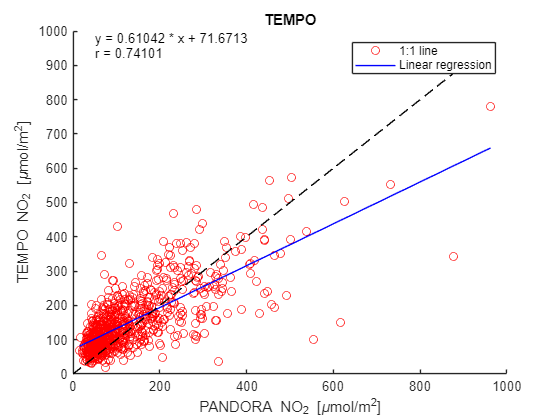

figure;
hold on;
plot(tempo_pandora_table.PANDORA_NO2, tempo_pandora_table.vertical_column_troposphere, 'ro')
plot(tempo_pandora_table.PANDORA_NO2, tempo_fit, 'b')
plot([0,max(cat(1,tempo_pandora_table.PANDORA_NO2, tempo_pandora_table.vertical_column_troposphere))],[0,max(cat(1,tempo_pandora_table.PANDORA_NO2, tempo_pandora_table.vertical_column_troposphere))], 'k--')
hold off,

ax = gca;
text(0.05*ax.XLim(2), ax.YLim(2), ['y = ' num2str(tempo_p(1)) ' * x + ' num2str(tempo_p(2)) newline 'r = ' num2str(tempo_corr(1,2))], 'VerticalAlignment', 'Top')
xlabel('PANDORA NO_{2} [\mumol/m^2]')
ylabel('TEMPO NO_{2} [\mumol/m^2]')
title('TEMPO')
legend('1:1 line', 'Linear regression')
if save_figs == true
    exportgraphics(gcf, fullfile(fig_folder, 'tempo_cor.png'))
end

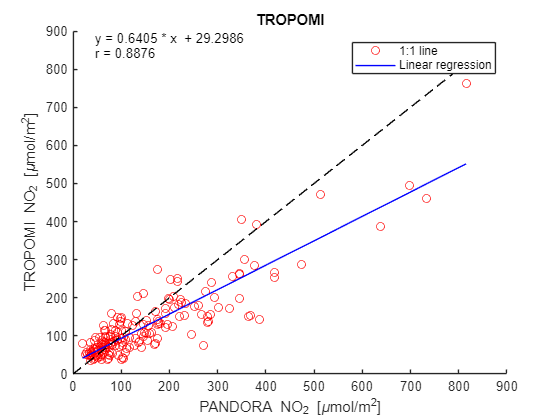



figure;
hold on;
plot(tropomi_pandora_table.PANDORA_NO2, tropomi_pandora_table.nitrogendioxide_tropospheric_column, 'ro')
plot(tropomi_pandora_table.PANDORA_NO2, tropomi_fit, 'b')
plot([0,max(cat(1,tropomi_pandora_table.PANDORA_NO2, tropomi_pandora_table.nitrogendioxide_tropospheric_column))],[0,max(cat(1,tropomi_pandora_table.PANDORA_NO2, tropomi_pandora_table.nitrogendioxide_tropospheric_column))], 'k--')
hold off;

ax = gca;
text(0.05*ax.XLim(2), ax.YLim(2), ['y = ' num2str(tropomi_p(1)) ' * x  + ' num2str(tropomi_p(2))  newline 'r = ' num2str(tropomi_corr(1,2))], 'VerticalAlignment', 'Top')
xlabel('PANDORA NO_{2} [\mumol/m^2]')
ylabel('TROPOMI NO_{2} [\mumol/m^2]')
title('TROPOMI')
legend('1:1 line', 'Linear regression')
if save_figs == true
    exportgraphics(gcf, fullfile(fig_folder, 'tropomi_cor.png'))
end

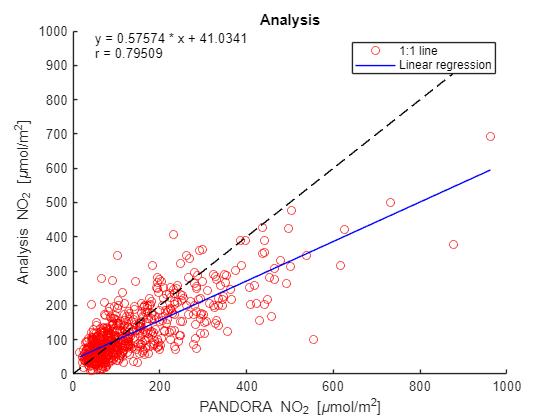


figure;
hold on;
plot(merged_pandora_table.PANDORA_NO2, merged_pandora_table.vertical_column_troposphere, 'ro')
plot(merged_pandora_table.PANDORA_NO2, merged_fit, 'b')
plot([0,max(cat(1,merged_pandora_table.PANDORA_NO2, merged_pandora_table.vertical_column_troposphere))],[0,max(cat(1,merged_pandora_table.PANDORA_NO2, merged_pandora_table.vertical_column_troposphere))], 'k--')
hold off;

ax = gca;
text(0.05*ax.XLim(2), ax.YLim(2), ['y = ' num2str(merged_p(1)) ' * x + ', num2str(merged_p(2)) newline 'r = ' num2str(merged_corr(1,2))], 'VerticalAlignment','top')
xlabel('PANDORA NO_{2} [\mumol/m^2]')
ylabel('Analysis NO_{2} [\mumol/m^2]')
title('Analysis')
legend('1:1 line', 'Linear regression')
if save_figs == true
    exportgraphics(gcf, fullfile(fig_folder, 'merged_cor.png'))
end

## Comparison of daily/weekly cycle 

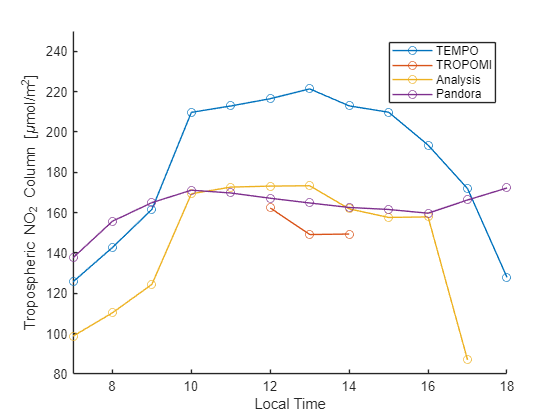

tz_local = 'America/New_York';
tempo_time_local = tempo_filtered.time; tempo_time_local.TimeZone = tz_local;

tempo_filtered.Hour = hour(tempo_filtered.time);
tempo_filtered.Weekday = weekday(tempo_filtered.time);
tempo_hourly_avg = groupsummary(tempo_filtered, "Hour", 'mean', 'vertical_column_troposphere');
tempo_daily_avg = groupsummary(tempo_filtered, "Weekday", 'mean', 'vertical_column_troposphere');

tropomi_filtered.Hour = hour(tropomi_filtered.time);
tropomi_filtered.Weekday = weekday(tropomi_filtered.time);
tropomi_hourly_avg = groupsummary(tropomi_filtered, "Hour", 'mean', 'nitrogendioxide_tropospheric_column');
tropomi_daily_avg = groupsummary(tropomi_filtered, "Weekday", 'mean', 'nitrogendioxide_tropospheric_column');

pandora_filtered.Hour = hour(pandora_filtered.Date);
pandora_filtered.Weekday = weekday(pandora_filtered.Date);
pandora_hourly_avg = groupsummary(pandora_filtered, "Hour", 'mean', 'NO2');
pandora_daily_avg = groupsummary(pandora_filtered, "Weekday", 'mean', 'NO2');

merged_filtered.Hour = hour(merged_filtered.time);
merged_filtered.Weekday = weekday(merged_filtered.time);
merged_hourly_avg = groupsummary(merged_filtered, "Hour", 'mean', 'vertical_column_troposphere');
merged_daily_avg = groupsummary(merged_filtered, "Weekday", 'mean', 'vertical_column_troposphere');

figure;
hold on
plot(tempo_hourly_avg.Hour-4, tempo_hourly_avg.mean_vertical_column_troposphere, 'o-');
plot(tropomi_hourly_avg.Hour-4, tropomi_hourly_avg.mean_nitrogendioxide_tropospheric_column, 'o-');
plot(merged_hourly_avg.Hour-4, merged_hourly_avg.mean_vertical_column_troposphere, 'o-');
plot(pandora_hourly_avg.Hour-4, pandora_hourly_avg.mean_NO2, 'o-');
hold off

xlabel('Local Time')
ylabel('Tropospheric NO_2 Column [\mumol/m^2]')
legend('TEMPO','TROPOMI','Analysis','Pandora')
xlim([11 22]-4)
ylim([80 250])
if save_figs == true
    exportgraphics(gcf, fullfile(fig_folder, 'daily_cycle.png'))
end

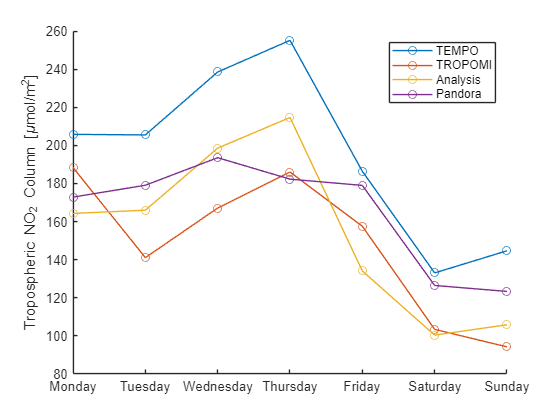


figure;
hold on
days = [2 3 4 5 6 7 1];
day_strings = ["Sunday" "Monday" "Tuesday" "Wednesday" "Thursday" "Friday" "Saturday"];
plot(tempo_daily_avg.Weekday, tempo_daily_avg.mean_vertical_column_troposphere(days), 'o-');
plot(tropomi_daily_avg.Weekday, tropomi_daily_avg.mean_nitrogendioxide_tropospheric_column(days), 'o-');
plot(merged_daily_avg.Weekday, merged_daily_avg.mean_vertical_column_troposphere(days), 'o-');
plot(pandora_daily_avg.Weekday, pandora_daily_avg.mean_NO2(days), 'o-');
hold off

% xlabel('day of Week')
ylabel('Tropospheric NO_2 Column [\mumol/m^2]')
legend('TEMPO','TROPOMI','Analysis','Pandora')
ax = gca;
ax.XAxis.TickLabels = day_strings(days);
if save_figs == true
    exportgraphics(gcf, fullfile(fig_folder, 'weekly_cycle.png'))
end

## Compare uncertainty as a function of parameters

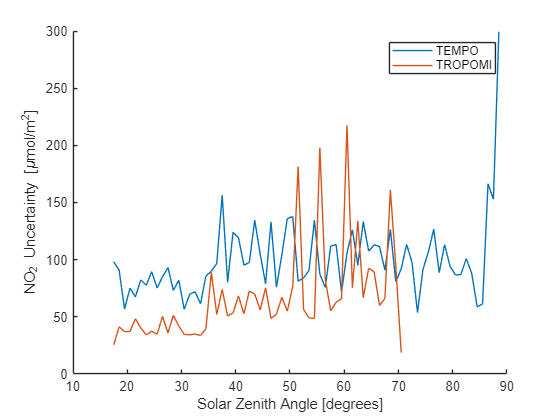

% Solar zenith angle, viewing zenith angle, cloud fraction, albedo
% use unfiltered data, create bins for each parameter to loop over, average
% uncertainty in corresponding bin
sza_bin_inc = 1;
vza_bin_inc = 1;
cld_frac_bin_inc = 0.01;
albedo_bin_inc = 0.01;

sza_bins = 0:sza_bin_inc:90;
vza_bins = 0:vza_bin_inc:90;
cld_frac_bins = 0:cld_frac_bin_inc:1;
albedo_bins = 0:albedo_bin_inc:1;

tempo_no2_u_sza = NaN(1,length(sza_bins)-1);
tempo_no2_u_vza = NaN(1,length(vza_bins)-1);
tempo_no2_u_cld_frac = NaN(1,length(cld_frac_bins)-1);
tempo_no2_u_albedo = NaN(1,length(albedo_bins)-1);

tropomi_no2_u_sza = NaN(1,length(sza_bins)-1);
tropomi_no2_u_vza = NaN(1,length(vza_bins)-1);
tropomi_no2_u_cld_frac = NaN(1,length(cld_frac_bins)-1);
tropomi_no2_u_albedo = NaN(1,length(albedo_bins)-1);

for i = 1:length(sza_bins)-1
    lower = sza_bins(i);
    upper = sza_bins(i+1);

    temp_tempo = tempo_table(tempo_table.solar_zenith_angle>=lower & tempo_table.solar_zenith_angle<upper,:);
    temp_tropomi = tropomi_table(tropomi_table.solar_zenith_angle>=lower & tropomi_table.solar_zenith_angle<upper,:);

    tempo_no2_u_sza(i) = mean(temp_tempo.vertical_column_troposphere_uncertainty, "omitmissing") ./ conversion_factor('trop-tempo');
    tropomi_no2_u_sza(i) = mean(temp_tropomi.nitrogendioxide_tropospheric_column_precision, "omitmissing");
end

for i = 1:length(vza_bins)-1
    lower = vza_bins(i);
    upper = vza_bins(i+1);

    temp_tempo = tempo_table(tempo_table.viewing_zenith_angle>=lower & tempo_table.viewing_zenith_angle<upper,:);
    temp_tropomi = tropomi_table(tropomi_table.viewing_zenith_angle>=lower & tropomi_table.viewing_zenith_angle<upper,:);

    tempo_no2_u_vza(i) = mean(temp_tempo.vertical_column_troposphere_uncertainty, "omitmissing") ./ conversion_factor('trop-tempo');
    tropomi_no2_u_vza(i) = mean(temp_tropomi.nitrogendioxide_tropospheric_column_precision, "omitmissing");
end

for i = 1:length(cld_frac_bins)-1
    lower = cld_frac_bins(i);
    upper = cld_frac_bins(i+1);

    temp_tempo = tempo_table(tempo_table.eff_cloud_fraction>=lower & tempo_table.eff_cloud_fraction<upper,:);
    temp_tropomi = tropomi_table(tropomi_table.cloud_fraction_crb>=lower & tropomi_table.cloud_fraction_crb<upper,:);

    tempo_no2_u_cld_frac(i) = mean(temp_tempo.vertical_column_troposphere_uncertainty, "omitmissing") ./ conversion_factor('trop-tempo');
    tropomi_no2_u_cld_frac(i) = mean(temp_tropomi.nitrogendioxide_tropospheric_column_precision, "omitmissing");
end

for i = 1:length(albedo_bins)-1
    lower = albedo_bins(i);
    upper = albedo_bins(i+1);

    temp_tempo = tempo_table(tempo_table.albedo>=lower & tempo_table.albedo<upper,:);
    temp_tropomi = tropomi_table(tropomi_table.surface_albedo_nitrogendioxide_window>=lower & tropomi_table.surface_albedo_nitrogendioxide_window<upper,:);

    tempo_no2_u_albedo(i) = mean(temp_tempo.vertical_column_troposphere_uncertainty, "omitmissing") ./ conversion_factor('trop-tempo');
    tropomi_no2_u_albedo(i) = mean(temp_tropomi.nitrogendioxide_tropospheric_column_precision, "omitmissing");
end


figure;
hold on
plot(sza_bins(1:end-1)+mean([sza_bins(1) sza_bins(2)]), tempo_no2_u_sza.*10^6)
plot(sza_bins(1:end-1)+mean([sza_bins(1) sza_bins(2)]), tropomi_no2_u_sza.*10^6)
hold off
xlabel('Solar Zenith Angle [degrees]')
ylabel('NO_2 Uncertainty [\mumol/m^2]')
legend('TEMPO', 'TROPOMI')
if save_figs == true
    exportgraphics(gcf, fullfile(fig_folder, 'sza.png'))
end

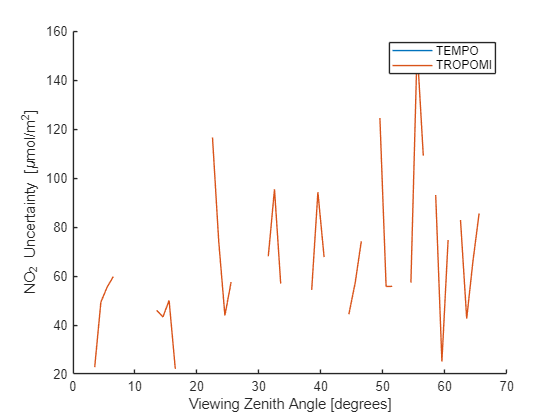


figure;
hold on
plot(vza_bins(1:end-1)+mean([vza_bins(1) vza_bins(2)]), tempo_no2_u_vza.*10^6)
plot(vza_bins(1:end-1)+mean([vza_bins(1) vza_bins(2)]), tropomi_no2_u_vza.*10^6)
hold off
xlabel('Viewing Zenith Angle [degrees]')
ylabel('NO_2 Uncertainty [\mumol/m^2]')
legend('TEMPO', 'TROPOMI')
if save_figs == true
    exportgraphics(gcf, fullfile(fig_folder, 'vza.png'))
end

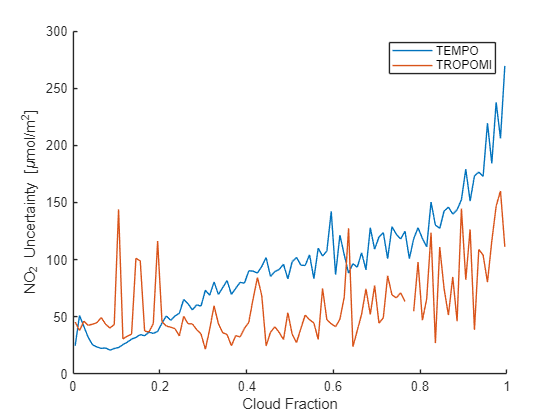


figure;
hold on
plot(cld_frac_bins(1:end-1)+mean([cld_frac_bins(1) cld_frac_bins(2)]), tempo_no2_u_cld_frac.*10^6)
plot(cld_frac_bins(1:end-1)+mean([cld_frac_bins(1) cld_frac_bins(2)]), tropomi_no2_u_cld_frac.*10^6)
hold off
xlabel('Cloud Fraction')
ylabel('NO_2 Uncertainty [\mumol/m^2]')
legend('TEMPO', 'TROPOMI')
if save_figs == true
    exportgraphics(gcf, fullfile(fig_folder, 'cld.png'))
end

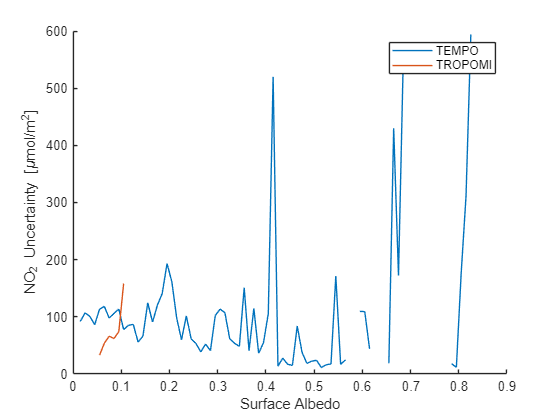


figure;
hold on
plot(albedo_bins(1:end-1)+mean([albedo_bins(1) albedo_bins(2)]), tempo_no2_u_albedo.*10^6)
plot(albedo_bins(1:end-1)+mean([albedo_bins(1) albedo_bins(2)]), tropomi_no2_u_albedo.*10^6)
hold off
xlabel('Surface Albedo')
ylabel('NO_2 Uncertainty [\mumol/m^2]')
legend('TEMPO', 'TROPOMI')
if save_figs == true
    exportgraphics(gcf, fullfile(fig_folder, 'a.png'))
end

% Functions to convert the different datasets to timetables
function table_out = tempo_table2timetable(table_in)
    table_out = table_in;
    table_out.time = datetime(table_out.time, 'ConvertFrom', 'epochtime', 'Epoch', '1980-01-06', 'TimeZone', 'UTC');
    table_out = table2timetable(table_out);
    table_out = sortrows(table_out, "time");
end

function table_out = tropomi_table2timetable(table_in)
    table_out = table_in;
    day_temp = datetime(table_out.time, "ConvertFrom", "epochtime", "Epoch",'2010-01-01', 'TimeZone', 'UTC');
    tropomi_times = NaT(size(day_temp), "TimeZone","UTC");

    for i = 1:length(tropomi_times)
        tropomi_times(i) = datetime(table_out.delta_time(i), "ConvertFrom", "epochtime","Epoch", day_temp(i) ,"TicksPerSecond",1000, "TimeZone","UTC");
    end

    table_out = removevars(table_out, "delta_time");
    table_out.time = tropomi_times;
    table_out = table2timetable(table_out);
    table_out = sortrows(table_out, "time");
end

function table_out = merged_table2timetable(table_in)
    table_out = table_in;
    table_out.time = datetime(table_out.time, 'ConvertFrom', 'posixtime', 'TimeZone', 'UTC');
    table_out = table2timetable(table_out);
    table_out = sortrows(table_out, "time");
end


function result = Rsq(y, yCalc) 
    result = 1 - sum((y - yCalc).^2)/sum((y - mean(y)).^2);
end

function MD = mean_difference(v,u)
    % satellite data minus pandora data
    n = numel(v);
    MD = sum(v-u) / n;
end

function MRD = mean_relative_difference(v,u)
    % satellite data minus pandora data
    n = numel(v);
    MRD = 100 * sum((v-u)./u,'all') / n;
end